# Diffusive SIR calibration using OC

First we need to compute a target:

[Rho_t, outTimes, dims, N_T, tMax, box, aLine] = Forward_Diffusive_SIR(0.479,0.125,false);

247 successful steps
0 failed attempts
1483 function evaluations
Elapsed time is 0.289385 seconds.


% Rho_t contains all the functional evaluations at spectral times outTimes
% in the spectral space box for the simulation time [0,tMax]. The total
% number of individuals at time t = 0 is given by N_T
[N1, N2, N] = dims{1,1:3};      % Gives the number of points in space
Target_t = Rho_t;

The resulting solution allows us to build an spectral interpolator in time by construction of `aLine`:

maskS = 1:N;
maskI = N+1:2*N;
maskR = 2*N+1:3*N;

IP = aLine.ComputeInterpolationMatrixPhys(0.5).InterPol;
rho_t = (IP * Rho_t)'/N_T;

We can plot the results of the interpolation as well: 

fprintf('\nInterpolation at time t = 0.5')


Interpolation at time t = 0.5

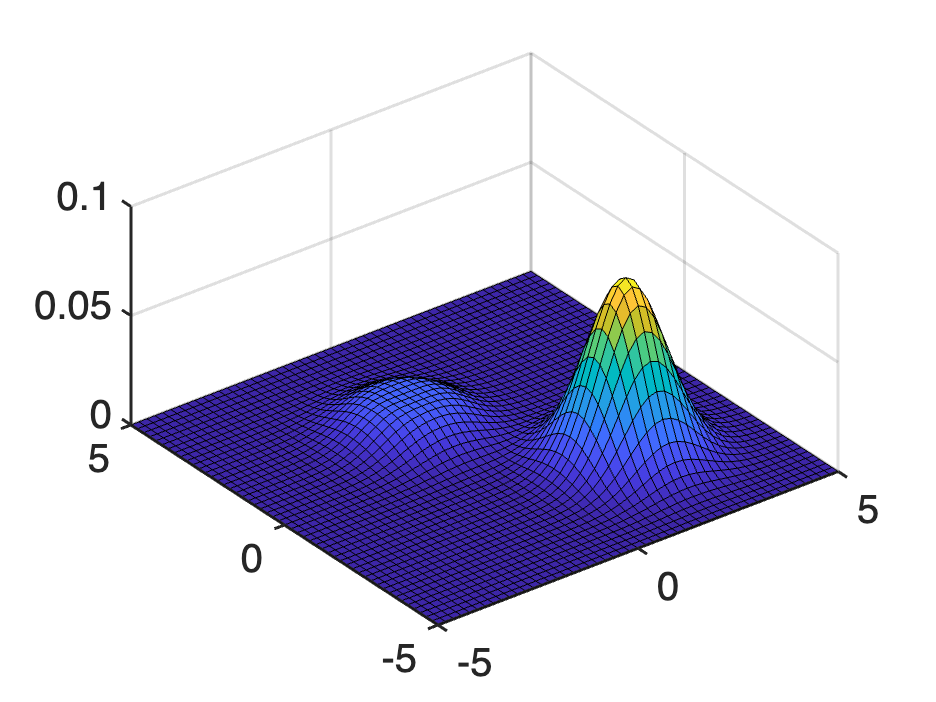

box.plot(rho_t(maskS),{});
xlabel(''); ylabel(''); zlabel('');

This is helpful since we want to solve the adjoint using an adaptive step method. To see this, let us compute a new *candidate* state:

c = 0.63696169;    % Infection rate: beta
w = 0.26978671;    % Recovery rate: gamma
[State_t, outTimes, dims, N_T, tMax, box, aLine] = Forward_Diffusive_SIR(c,w,false);

261 successful steps
0 failed attempts
1567 function evaluations
Elapsed time is 0.269764 seconds.


With this, we have all the ingredients to evaluate the adjoint:

636 successful steps
1 failed attempts
3823 function evaluations
Elapsed time is 1.445057 seconds.


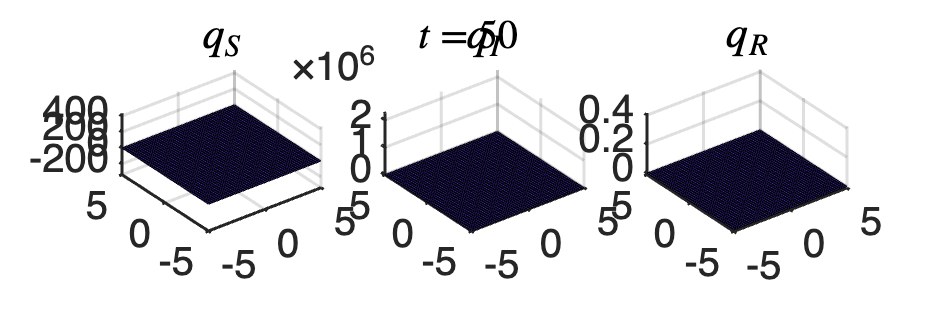

Q_t = Adjoint_Diffusive_SIR(c,w, State_t, Target_t, dims, N_T, box, aLine, true);

The adjoint is used to compute the derivative of the reduced objective functional:

% Retrieve involved components from state
State_o    = State_t(:,maskS);       I = State_t(:,maskI);       R = State_t(:,maskR);
% Retrieve each component of the target
Ta_S = Target_t(:,maskS);   Ta_I = Target_t(:,maskI);   Ta_R = Target_t(:,maskR);
% Retrieve each component of the adjoint
q_S  = Q_t(:,maskS);         q_I = Q_t(:,maskI);         q_R = Q_t(:,maskR);

% Integration weights
Int_Spatial = box.ComputeIntegrationVector;
Int_Time    = aLine.ComputeIntegrationVector;
% Partial derivatives
dbeta  = Int_Time * (Int_Spatial * (State_o .* I .* ( q_I - q_S ))')';
dgamma = Int_Time * (Int_Spatial * (I .* ( q_R - q_I ))')';
% Gradient
display(['Scaled derivative:  ', num2str([dbeta,dgamma]/(N_T^2))])

Scaled derivative:  0.18326    0.084982


Let us also compute the objective value:

f = 0.5 * Int_Time * (Int_Spatial * ((State_o-Ta_S).^2 + (I-Ta_I).^2 + (R-Ta_R).^2)')';
display(['Scaled objective:  ', num2str(f/(N_T^2))])

Scaled objective:  0.03314


We save the current state before running the algorithm itself:

State_Init = State_t;

## A projected gradient-descent algorithm

Now we aim to solve the OC problem using an optimisation scheme. For this we designed additional scripts to evaluate only the state and adjoint separately.

Pts = box.Pts;
[rho_ic,N_T] = InitialCondition(Pts.y1_kv,Pts.y2_kv,Int_Spatial,N);

The function `State` computes the state variable for a given pair of parameters `beta` and `gamma`. Since the initial condition does not change accross iterations, we provide it as an argument to reduce precomputations. Similarly, we provide the objects `dims`, `box`, and `aLine` so that the dimensions of the solution coincide with the state and are defined over the same domain of interest.

`    State(beta,gamma, rho_ic, dims, box, aLine)`

Once a state has been computed, we can compute its corresponding adjoint using the function Adjoint.

`    Adjoint(beta,gamma, State_t, Target_t, dims, box, aLine)`

We proceed similarly with the `Objective` and `Gradient` functions:

`    Objective(State_t, Target_t, N, Int_Spatial, Int_Time)`

`    Gradient(State_t, Target_t, Adjoint_t, N, Int_Spatial, Int_Time)`

Finally, we will also need a projection operator into the unit box [0,1]^2:

Proj = @(x) min( max(x,0), 1);

Now we can write a code for the algorithm:

Nb_Its = 100;       % Number of iterations
critical = 1;      % Report status

% Define majorant function
quad =@(x,y, h_y, dh_y, L) h_y + dot(x-y,dh_y) + 0.5 * L * sumsqr(x-y);

% Define objects to store information across iterates
crit    = zeros(Nb_Its + 1, 1);
State_t = State_Init;
f       = Objective(State_t, Target_t, N, Int_Spatial, Int_Time);
f       = f/(N_T^2); % We scale the system
crit(1) = f;
betas   = zeros(Nb_Its, 1);
dbetas  = zeros(Nb_Its, 1);
gammas  = zeros(Nb_Its, 1);
dgammas = zeros(Nb_Its, 1);
dnorms  = zeros(Nb_Its, 1);
time    = zeros(Nb_Its,1);

% Stopping criteria
Stop_norm = 1e-7;       % Error between consecutive iterations
Stop_crit = 1e-9;       % Error between consecutive functional evaluations
tols = 1e-7;            % Tolerance for PDE solvers

fprintf('     It  |   f(α)  | ‖df(ωₖ)‖ᵣ |   Time  |    β    |   γ     \n')

     It  |   f(α)  | ‖df(ωₖ)‖ᵣ |   Time  |    β    |   γ     


disp(strcat( repmat('–',1,62) ))

––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––



% Initialisation
alpha_0 = [c, w];
beta = alpha_0(1);    gamma = alpha_0(2);
% Define variables
alpha = alpha_0;
omega = alpha;
theta = 1;  % Inertia parameter
eta = 10;   % Scaling for backtracking
L = 6;     % Approximation of the Lipschitz constant
I = 10;     % Number of iterations for backtracking

timing = 0.0;
% Iterations
for it = 1:Nb_Its
    % Start measuring time
    start = tic;
    
    alpha_old = alpha;
    t_old = theta;
    f_old = f;
    
    %---------------------------------------------------------------
    % Function evaluation and adjoint for omega
    State_o   = State(omega(1),omega(2), rho_ic, dims, box, aLine,tols);
    Adjoint_o = Adjoint(omega(1),omega(2), State_o, Target_t, dims, box, aLine,tols);
    h_y  = Objective(State_o, Target_t, N, Int_Spatial, Int_Time)/(N_T^2);
    dh_y = Gradient(State_o, Target_t, Adjoint_o, N, Int_Spatial, Int_Time)/(N_T^2);
    
    if norm(dh_y,'inf') > 1.1
        scale = 1/norm(dh_y);
    else
        scale = 1.0;
    end
    %---------------------------------------------------------------
    % backtracking
    for i = 0:I
        % temporary approximation of Lipschitz constant
        L_tmp = eta^i * L;
        b = 1/L_tmp;
        % Gradient and proximal step
        u = omega - b * scale * dh_y;
        %fprintf('u = (%.6f,%.6f) \n',u)
        p = Proj(u);
        % Compute state to test validation of L_tmp
        State_p = State(p(1),p(2), rho_ic, dims, box, aLine,tols);
        h_p     = Objective(State_p, Target_t, N, Int_Spatial, Int_Time)/(N_T^2);
        %fprintf('(h_y, h_p) = (%.6f,%.6f) \n',[h_y, h_p])
        %fprintf('(h, q) = (%.6f,%.6f) \n',[h_p,quad(p,omega, h_y,dh_y, L_tmp)])
        if h_p <= quad(p,omega, h_y,dh_y, L_tmp/scale)
            break
        end
    end
    %---------------------------------------------------------------
    % Update control
    L     = L_tmp;
    alpha = p;
    % inertia update
    theta = (it + 2.2)/(2.2);
    omega = alpha + ((t_old - 1)/theta) * (alpha - alpha_old);
    
    % Measure time up to this point!
    timed = toc(start);
    timing = timing + timed;
    % Store information
    % --------------------------------------------------------------
    time(it+1) = timing;
    crit(it+1) = h_p;
    betas(it)   = beta;
    %dbetas(it)  = df(1);
    gammas(it)  = gamma;
    %dgammas(it) = df(2);
    %dnorms(it)  = norm(df,'inf');
    
    % Display if needed
    if(mod(it,critical)==0)
        fprintf('* %6.0f | %.1e | %.3e | %7.2f | %6.5f | %6.5f \n', ...
            [it, h_p, norm(dh_y,inf), timing, ...
            alpha(1), alpha(2)])
    end
    % --------------------------------------------------------------
    
    if norm(alpha - alpha_old) < Stop_norm * sqrt(2)
        fprintf('‖αₖ - p‖ < %.e\n', Stop_norm)
        display(alpha)
        break
    end
    
    if abs(f-h_p) < Stop_crit
        fprintf('|f(αₖ) - f(p)| < %.e\n', Stop_crit)
        display(alpha)
        break
    end
    f = h_p;
    
end

*      1 | 2.7e-02 | 1.833e-01 |    0.93 | 0.60642 | 0.25562 
*      2 | 2.1e-02 | 1.507e-01 |    1.68 | 0.58130 | 0.23678 
*      3 | 1.4e-02 | 1.402e-01 |    2.39 | 0.55606 | 0.20893 
*      4 | 6.6e-03 | 1.475e-01 |    3.13 | 0.53072 | 0.17363 
*      5 | 1.3e-03 | 9.973e-02 |    3.81 | 0.50493 | 0.13993 
*      6 | 3.1e-04 | 5.324e-02 |    4.62 | 0.48978 | 0.12210 
*      7 | 6.2e-04 | 1.408e-01 |    5.26 | 0.48004 | 0.11357 
*      8 | 8.6e-04 | 1.705e-01 |    5.86 | 0.47350 | 0.11085 
*      9 | 7.9e-04 | 1.491e-01 |    6.44 | 0.46914 | 0.11147 
*     10 | 6.2e-04 | 1.062e-01 |    7.04 | 0.46646 | 0.11368 
*     11 | 4.8e-04 | 6.355e-02 |    7.65 | 0.46513 | 0.11637 
*     12 | 3.9e-04 | 4.688e-02 |    8.31 | 0.46490 | 0.11891 
*     13 | 3.2e-04 | 4.964e-02 |    8.92 | 0.46556 | 0.12099 
*     14 | 2.6e-04 | 4.777e-02 |    9.53 | 0.46687 | 0.12253 
*     15 | 1.9e-04 | 4.239e-02 |   10.15 | 0.46863 | 0.12356 
*     16 | 1.3e-04 | 3.478e-02 |   10.75 | 0.47064 | 0.12417 
*     17

|f(αₖ) - f(p)| < 1e-09


alpha =     0.4790    0.1250


disp(strcat( repmat('–',1,62) ))

––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––


fprintf('\n‖df(αₖ)‖ ≈ ‖df(p)‖ = %f.\n\n',norm(dh_y))


‖df(αₖ)‖ ≈ ‖df(p)‖ = 0.000075.



fprintf('\nAlgorithm stopped after %.4f seconds and %.0f iterations.\n\n', ...
    [time(it+1),it])


Algorithm stopped after 42.6677 seconds and 76 iterations.

